%clear variables;
mkdir('./output_data');

load('stringmain_n_10_fe.mat');

alpha = [0.5 1 5 10 20 100 0.5];


for i = 1:size(alpha, 2)
    args{1}.param = alpha(i);
    out = string_descend(args{:});
    filename = sprintf('output_param_%d.mat', i);
    save(filename, 'out');
end 

Iteration: 1  W max:2.900e-04  Error:1.238e-04  S: 3.983531e-03  Alignment:NaN Length: 2.714393e-01




args{15} = 'deterministic';
args{16} = 1;
out = string_descend(args{:});
save('./data/output_det.mat', 'out');

%Figure 3A

W05 = load('./data/output_param_6.mat', 'out');
W05 = W05.out.W;
W1 = load('./data/output_param_1.mat','out');
W1 = W1.out.W;
W5 = load('./data/output_param__2.mat','out');
W5 = W5.out.W;
W10 = load('./data/output_param_3.mat','out');
W10 = W10.out.W;
W20 = load('./data/output_param_4.mat', 'out');
W20 = W20.out.W;
W100 = load('./data/output_param_5.mat', 'out');
W100 = W100.out.W;

W1d = load('./data/output_det.mat','out');
W1d = W1d.out.W;

xx = linspace(0,1,10);

plot(xx, W05,'r', xx, W1, 'k', xx, W5, 'b', xx, W10, 'm', xx, W20, 'g', xx, W100, 'y', xx, W1d, 'k--', 'LineWidth', 1.5)

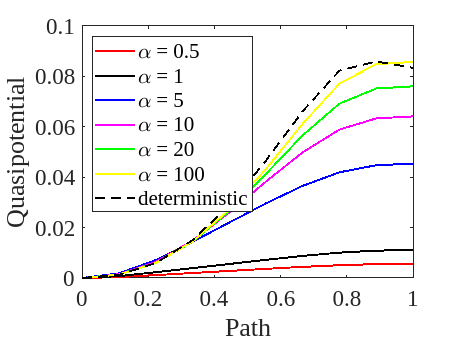

legend('\alpha = 0.5','\alpha = 1', '\alpha = 5','\alpha = 10', '\alpha = 20', '\alpha = 100', 'deterministic', 'Location', 'northwest')
%title('2-bead cluster \rightarrow 2-bead cluster');
ylabel('Quasipotential');
xlabel('Path')
xticks([0 0.2 0.4 0.6 0.8 1])
set(gca, "FontName", "Times New Roman", "FontSize", 18)

%Figure 3B

load('systems.mat', 'system2'); 
param = 1;
system2.a = @(x)param*2./(1+exp(20*(abs(x)-0.75)));
system2.param = param; 
system = system2;

x = [-1 0 -1 0 0 1];

tic;
eps_range = logspace(log10(1/200), log10(1/100), 10);
[~,all_times, stopflags] = escape_statistics_param(system, x, eps_range, 5000);%trials

    20

    20

    20

    20



toc


mean_times05 = zeros(size(eps_range));
mean_times1 = zeros(size(eps_range));
mean_times5 = zeros(size(eps_range));
mean_times10 = zeros(size(eps_range));
mean_times20 = zeros(size(eps_range));


%want to sort out only 2-bead cluster to 2-bead cluster transitions
for i = 1:length(mean_times1)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times1(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end



param = 0.5;
[~,all_times, stopflags] = escape_statistics_param(system, x, eps_range, 5000);
for i = 1:length(mean_times05)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times05(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end

param = 5;
[~,all_times, stopflags] = escape_statistics_param(system, x, eps_range, 5000);
for i = 1:length(mean_times5)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times5(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end

param = 10;
eps10 = eps_range(2:10)
[~,all_times, stopflags] = escape_statistics_param(system, x, eps10, 5000);
for i = 1:length(mean_times10)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times10(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end

eps20 = eps_range(4:10)
param = 20;
[~,all_times, stopflags] = escape_statistics_param(system, x, eps20, 5000);
for i = 1:length(mean_times10)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times10(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end


eps100 = eps_range(5:10)
param = 100;
[~,all_times, stopflags] = escape_statistics_param(system, x, eps100, 5000);
for i = 1:length(mean_times100)
    all_times1= cell2mat(all_times(i));
    stopflags1 = cell2mat(stopflags(i));
    mean_times100(i) = sum(all_times1(find(stopflags1 == 1)))/sum(stopflags1 == 1);
end


eps_range = logspace(log10(1/200), log10(1/100), 10);
fit_x = 1./eps_range; 

fit_y05 = log(mean_times05);
fit_y1 = log(mean_times1);

Unrecognized function or variable 'mean_times1'.

fit_y5 = log(mean_times5);
fit_y10 = log(mean_times10);
fit_y20 = log(mean_times20);
fit_y100 = log(mean_times100);


%energy barrier hieghts
S05 = W05(end);
S1 = W1(end);
S5 = W5(end);
S10 = W10(end);
S20 = W20(end);
S100 = W100(end);

intercept05 = mean(fit_y05) - S05*mean(fit_x);
intercept1 = mean(fit_y1) - S1*mean(fit_x);
intercept5 = mean(fit_y5) - S5*mean(fit_x);
intercept10 = mean(fit_y10) - S10*mean(fit_x);
intercept20 = mean(fit_y20) - S20*mean(fit_x(3:10));
intercept100 = mean(fit_y100) - S100*mean(fit_x(5:10));


% Plot MC results with quasipotential slope

h = plot(fit_x(5:10), fit_y100, 'yx', fit_x, S100*fit_x + intercept100, 'y-', "Linewidth", 2, "MarkerSize", 10)
hold on 
plot(fit_x(3:10), fit_y20, 'gx', fit_x, S20*fit_x+intercept20, 'g-', "Linewidth", 2, "MarkerSize", 10)
plot(fit_x, fit_y10, 'mx', fit_x, S10*fit_x+intercept10, 'm-', fit_x, fit_y5, 'bx', fit_x, S5*fit_x+intercept5, 'b-', fit_x, fit_y1, 'kx', fit_x, S1*fit_x+intercept1, 'k-', fit_x, fit_y05, 'rx', fit_x, S05*fit_x+intercept05, 'r-', "Linewidth", 2, "MarkerSize", 10);
plot(fit_x, fit_y1, fit_x, S1*fit_x+intercept1)
set(gca, "FontName", "Times New Roman", "FontSize", 18)
yticks([12 14 16 18 20]);
ylim([12 20]);
xticks([100 120 140 160 180 200]);
xlim([100 200])
xticklabels({'100', '120', '140', '160', '180', '200'})
xlabel('1/\epsilon', "FontSize", 22); ylabel('log(\tau)', "FontSize", 20); 

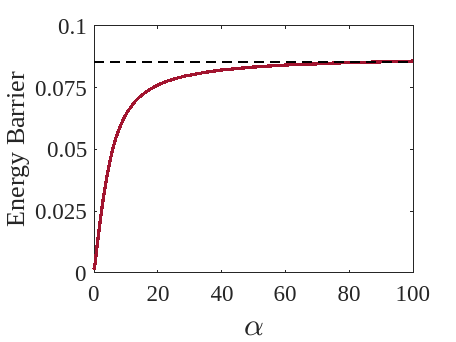

%Figure 3C
%cluster to cluster 
load('stringmain_n_10_fe.mat');

alpha = [0.01 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1:30 35:5:100];
det = [0.0856*ones(1,54)]; %deterministic energy barrier height 

energy_barrier = zeros(1, size(alpha,2));
for i = 1:size(energy_barrier,2)
    args{1}.param = alpha(i);
    out = string_descend(args{:});
    energy_barrier(i) = out.W(end);
end
%load("./data/energy_barrier_data.mat", "energy_barrier");

b = plot(alpha, energy_barrier, 'Color', [0.6350 0.0780 0.1840], "Linewidth", 2.5, "MarkerSize", 18);
ylabel("Energy Barrier", 'FontSize',18);
hold on 
d = plot(alpha, det, 'k--',  "Linewidth", 1.5, "MarkerSize", 18);
hold off
set(gca, "FontName", 'Times New Roman', "FontSize", 18);
xlabel("\alpha", 'FontSize',24); 
xticks([0 20 40 60 80 100])
yticks([0 0.025 0.05 0.075 0.1]);